clf;
%%Testskript für die Blattauslegung mit Betz/Schmitz
%%zum erstellen eines neuen Profils Rotorradius, schnelllaufzahl und
%%Blattanzahl. Danach noch den profilnamen eingeben (z. Zt. gehen nur NACA
%%4-Digit Profile. der Radius bei dem das Profil hinzugefügt werden soll, 
%%Anstellwinkel,  und Postion der Blattachse eingeben. Zum Bearbeiten muss
%%"edit" auf 1 gesetzt sein. Ansonsten werden nur vorhanden Profile
%%geplottet

%%globale Variablen des Rotors
R=50;           %%Rotorradius [m]
lamda_A=7;      %%Schnelllaufzahl   [1]
z=3;            %%Blattanzahl       [1}

%%lokale Variablen zum einfgügen der Profile
name='NACA 1412';    %%Profilname gerade nur NACA 4-digit profile, z.B. "NACA0012", oder "Cir_2.1" für 2.1m kreis
%%alpha_A=6;          %%Anstellwinkel     [°]
t=0.25;             %%Position Blattachse
r=50;               %%Position des Profils auf dem Blatt

edit=1;             %%edit an oder aus


## load foildatabase

fileName='foils_imported.dat';

foil_db=readtable(fileName)

foil_db = 38×7 table
        foil_name         AoA_eps    CL_eps    CD_eps     AoA_lift    CL_lift    CD_lift
    __________________    _______    ______    _______    ________    _______    _______

    {'NACA 1408'     }      7.5      0.9092    0.01098         8      0.9574     0.01209
    {'NACA 1410'     }        8      0.9802    0.00945         9      1.0658     0.01224
    {'NACA 1412'     }      8.5      1.0491    0.01049        16      1.5737     0.02843
    {'NACA 23012'    }      8.5      1.1156    0.00874      17.5      1.7133     0.03341
    {'NACA 23015'    }      6.5       0.841    0.00798      16.5      1.6284     0.02997
    {'NACA 23024'    }      6.5      0.7343    0.00982      17.5      1.2962     0.04516
    {'NACA 2410'     }      

## check if foil exists in db

Index =find(strcmp(name,foil_db.foil_name))

Index = 3

## Profile erstellen und anhängen

if edit==1
   if exist('prof')==0
       prof=blade_root(R)
       if r>= 0.15*R
            prof(3)=foil_transform(R,r,name,lamda_A,z, t,foil_db);
       else
            disp('Profil ist zu nah an der Blattwurzel. Anderen Profilposition waehlen!')    
       end       
     else
       if check_existing(prof,r) == 0 & r>= 0.15*R
            l=length(prof);
            prof(l+1)=foil_transform(R,r,name,lamda_A,z, t,foil_db);
            prof=bld_sort(prof);
       else
           disp('Profil an dieser Blattposition existiert bereits oder ist zu nah an der Blattwurzel. Anderen Profilposition waehlen!')
       end
   end
end

existing = logical
   0


Index = 3

## plot der profile

bld_plot(prof)

l = 4

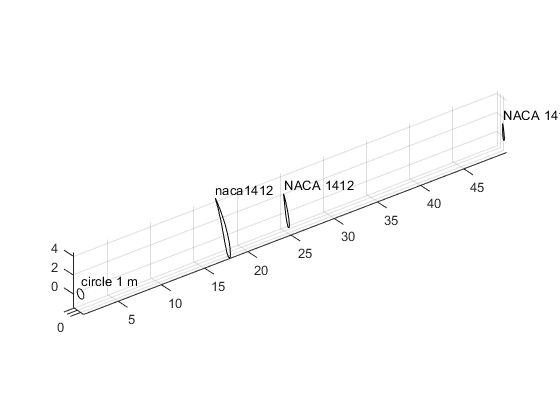

grid on